# PNNL and Me Chemometric Toolbox: Building chemometric models with your own data

Copyright 2022 Battelle Memorial Institute

This script will perform basic chemometric modeling and plotting of your own data. Your data should be formatted according to the `PNNL_and_Me_Format_My_Data.mlx` file, with your data matrices in a file named toolbox_user_data.mat. If you have your data saved in Excel documents, you can use the `PNNL_and_Me_Format_My_Data.mlx` file to import and save it to MATLAB. 

A file called `toolbox_user_data.mat` has been provided to you with example data in case you do not yet have your own data. 

NOTE: Run this script in a folder which contains your data in a .mat file and this .mlx script file.  Alternatively, make sure to "add to path" all the folders containing the script and your data (see MathWorks documentation for [`addpath`](https://www.mathworks.com/help/matlab/ref/addpath.html)). 

clearvars
load('pnnl_chemometric_user_data.mat')
whos

  Name                     Size               Bytes  Class     Attributes

  A_train                 20x1713            274080  double              
  A_unknown               12x1713            164448  double              
  C_train                 20x3                  480  double              
  C_validation            12x3                  288  double              
  ConcentrationUnits       1x4                    8  char                
  ConstituentNames         1x3                  318  cell                
  WavenumberLabel          1x12                  24  char                
  Wavenumbers              1x1713             13704  double              



You should have variables named `A_train`, `C_train`, ConstituentNames, `ConcentrationUnits`, `WavenumberLabel`, and `Wavenumbers`. You might also have `A_unknown` and/or `C_validation`. 

calibrationDataPresent = exist('A_train','var') && exist('C_train','var');
assert(calibrationDataPresent,'You must have at least A_train and C_train to peform basic chemometric modeling.')

unknownDataPresent = exist('A_unknown','var');
validationDataPresent = exist('C_validation','var');

# *A word of caution*

This script hasn't yet been tested using your data. You may experience errors as you run this script. The following section provides basic terminology and matrix descriptions which will show you the assumptions that this script is making.  Familiarity with MATLAB will help you with more extensive troubleshooting. 

### Basic Terminology

The PNNL Chemometrics Toolbox uses the following terminology. 

- *m* — the number of wavenumbers/wavelengths/frequencies (pixels) reported by your spectrometer. 

- *n* — the number of constituents in your samples; in other words, the number of species in your system which produce a measurable response in that system and, in the case of the training (calibration) set, the species for which you have quantitative values.

- *p* — the number of spectra in your training or validation dataset. Generally, we assume you have one spectrum per sample (averaging several spectra into one spectrum reduces random noise!).  

- A matrix — the matrix containing your spectra in row format (one spectrum per row).

- C matrix — the matrix containing your concentration data, or other quantitative data which corresponds to parameters that produce a measureable signal in the spectra, in row format (one sample per row). 

- Training set — a set of data which is used to calibrate your measurement technique; usually composed of standards or samples with precisely known concentrations. You MUST have both an A and C matrix for the training set, or else you cannot perform calibration! 

- Validation set — a set of data which is used to test the measurement error of your chosen technique; usually composed of standards or samples with precisely known concentrations, but different concentrations from the training set. You MUST have both an A and C matrix in order to truly have a validation set. 

- Unknown set — a set of spectra for samples with unknown concentrations of your target species (constituents). You do not have a C matrix that accompanies the spectra. 

### Proper Data Format

The PNNL Chemometrics Toolbox assumes that your data is organized in row format. This means that your A  matrices have one spectrum per row, and a number of columns equal to the frequencies you are trying to model; i.e. your A matrices should be *p *x* m*. Your C matrices have one sample per row, and a number of columns equal to the optically active constituents which you are trying to measure; i.e. your C matrices should be *p* x *n*. 

NOTE: The number of rows in your training set A and C matrices MUST be the same. The number of rows in your validation set A and C matrices MUST be the same. 

If you do not have a C matrix for your validation set, then the set is more properly called an unknown dataset. In this case, you can use many parts of this script, but not all (e.g. you cannot get an RMSEP if you do not have a $C_\textrm{validation}$). 

- `Wavenumbers` — a 1 x *m* matrix containing the spectral axis for your spectra. If some of your spectra use a different axis, you will need to perform data alignment, as only one axis can be used in this script. 

- `WavenumberLabel` — a string with the proper label and units for your spectral axis. E.g. '`Wavelength (nm)'` 

- ConstituentNames — a cell of *n *strings containing the names of the chemical constituents in the same order as the columns of C_train. 

- `A_train` — a $p_\textrm{train}$ x *m *matrix containing the training set spectra, where *p* is the number of spectra you've taken of your training set. 

- `C_train` — a $p_\textrm{train}$ x *n* matrix containing the concentrations of each of your measured consituents in the training set, where *p* is the same as in A_train. All concentrations should be in the same units for the purpose of plot labels (if this is not possible, then you may have to edit some plot labels by hand). 

- `A_unknown` — a $p_\textrm{unknown}$ x *m* matrix containing spectra measured from samples that are not in your training set, where $p_\textrm{unknown}$ is the number of spectra taken for this second set. 

- `C_validation` — a $p_\textrm{unknown}$ x *n* matrix containing the concentrations of each of your measured constituents in the second set of data (A_unknown), now called the validation set. Here, $p_\textrm{unknown}$ must be the same as in `A_unknown`, and *n* must be the same as in `C_train`. Furthermore, the order of columns in `C_validation` must match the order of columns in `C_train` (e.g. column 1 is compound A and column 2 is compound B in **both** `C_train` and `C_validation`). If you do not have this data, then you have an "unknown" sample set.

## Plot Data

MATLAB Tip: At the right hand side of the Live Editor window, there are two icons (directly right of the scroll bar); click the "Show outputs inline" to show plots within the script as you generate them.

It is a good idea to look at your data before you begin analyzing it. 

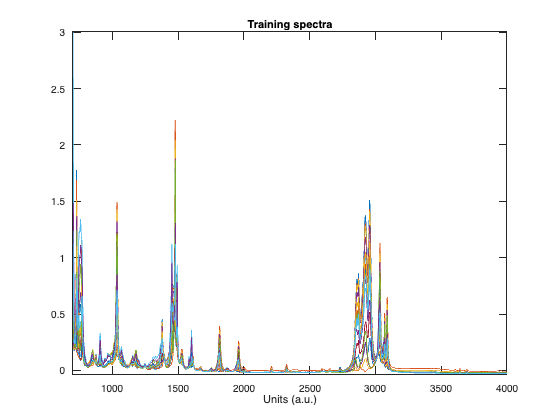

plot(Wavenumbers,A_train)
title("Training spectra")
xlabel(WavenumberLabel)
axis tight % this command sets the axes to the exact limits of your data

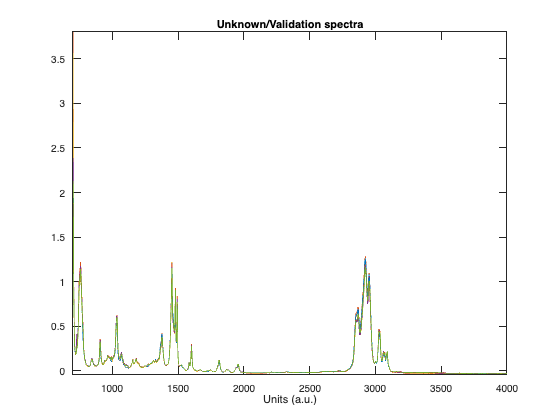

if unknownDataPresent  % If you have unknown/validation spectra
    plot(Wavenumbers,A_unknown)
    title("Unknown/Validation spectra")
    xlabel(WavenumberLabel)
end
axis tight

## Chemometric Analysis 

### Classical Least Squares

Build the model. 

[~, B_cls, K_cls] = pnnl_cls(A_train, C_train, A_train);

Measure concentrations in the available data sets. Calculate root mean square errors for the training, cross validation, and validation sets.

if calibrationDataPresent % If you have a training set
    [~, ~, C_cls, RMSEC_cls, C_cls_cv, RMSECV_cls,~] = ...
        pnnl_compute_predictions(@pnnl_cls,"",A_train,C_train,A_train,C_train);
end
if unknownDataPresent % If you have unknown spectra
    [C_cls_pred, ~, ~] = pnnl_cls(A_train, C_train, A_unknown);
end
if validationDataPresent % If you have the validation set
    [C_cls_pred, RMSEP_cls, ~, ~, ~, ~,~] = ...
        pnnl_compute_predictions(@pnnl_cls,"",A_train,C_train,A_unknown,C_validation);
end
if validationDataPresent
    pnnl_display_rmse("CLS:",ConstituentNames,RMSEC_cls,RMSECV_cls,RMSEP_cls)
elseif calibrationDataPresent
    pnnl_display_rmse("CLS:",ConstituentNames,RMSEC_cls,RMSECV_cls)
end

--------------------------------------------------
    CLS:             A             B             C
   RMSEC        4.2721        2.3784        5.6857
  RMSECV        5.1043        3.0807        6.7847
   RMSEP         7.895        2.6988        9.1105
--------------------------------------------------


The columns of the RMSE matrices are in the same order as in the C_train matrix. RMSEC is the error of the concentrations measured by the model on the calibration data versus the known calibration sample concentrations. RMSECV is the error of the concentrations measured by the model on the calibration data during the cross validation procedure versus the known calibration sample concentrations. RMSEP is the error of the concentrations measured by the model on the validation data versus the known validation sample concentrations. 

C_cls is the concentrations of the training set, as measured by the model. C_cls_cv are the concentrations measured by the model during the cross validation protocol. C_cls_pred is the concentrations of the validation/unknown set, as measured by the calibrated model. K_cls contains the normalized extinction coefficient(s). 

### Principal Component Regression

Principal Component Regression analysis of your data can be conducted with the following code.

### Action needed

You must set *r,* which is the number of principal components to be retained in the PCR model and latent variables in the PLS model.  

r=3;

Build the model. 

[~, B_pcr] = pnnl_pcr(A_train, C_train, A_train, r);

Measure concentrations in the available data sets. Calculate root mean square errors for the training, cross validation, and validation sets.

if calibrationDataPresent % If you have a calibration set
    [~, ~, C_pcr, RMSEC_pcr, C_pcr_cv, RMSECV_pcr, ~] = ...
        pnnl_compute_predictions(@pnnl_pcr,"",A_train,C_train,A_train,C_train,r);
end
if unknownDataPresent % If you have the unknown spectra
    [C_pcr_pred, ~] = pnnl_pcr(A_train, C_train, A_unknown,r);
end
if validationDataPresent % If you have the validation set
    [C_pcr_pred, RMSEP_pcr, ~, ~, ~, ~, ~] = ...
        pnnl_compute_predictions(@pnnl_pcr,"",A_train,C_train,A_unknown,C_validation,r);
end
if validationDataPresent
    pnnl_display_rmse("PCR:",ConstituentNames,RMSEC_pcr,RMSECV_pcr,RMSEP_pcr)
elseif calibrationDataPresent
    pnnl_display_rmse("PCR:",ConstituentNames,RMSEC_pcr,RMSECV_pcr)
end

--------------------------------------------------
    PCR:             A             B             C
   RMSEC        4.2787        2.3856        5.6681
  RMSECV        5.1022        2.9924        6.7526
   RMSEP        7.7847        2.2831        9.9695
--------------------------------------------------


### Partial Least Squares (mean centered)

Partial least squares (PLS) analysis of your data can be conducted with the following code: 

Build the model with mean centering. 

meanCentered = true;
[~, B_plsmc] = pnnl_pls(A_train, C_train, A_train, r, meanCentered);

Measure concentrations in the available data sets. Calculate root-mean-square errors for the training, cross validation, and validation sets.

if calibrationDataPresent % If you have a calibration set
    [~, ~, C_plsmc, RMSEC_plsmc, C_plsmc_cv, RMSECV_plsmc, ~] = ...
        pnnl_compute_predictions(@pnnl_pls,"",A_train,C_train,A_train,C_train,r,meanCentered);
end
if unknownDataPresent % If you have unknown spectra
    [C_plsmc_pred, ~] = pnnl_pls(A_train, C_train, A_unknown, r, meanCentered);
end
if validationDataPresent % If you have the validation set
    [C_plsmc_pred, RMSEP_plsmc, ~, ~, ~, ~, ~] = ...
        pnnl_compute_predictions(@pnnl_pls,"",A_train,C_train,A_unknown,C_validation,r,meanCentered);
end
if validationDataPresent
    pnnl_display_rmse("PLS (mc):",ConstituentNames,RMSEC_plsmc,RMSECV_plsmc,RMSEP_plsmc)
elseif calibrationDataPresent
    pnnl_display_rmse("PLS (mc):",ConstituentNames,RMSEC_plsmc,RMSECV_plsmc)
end

--------------------------------------------------
PLS (mc):             A             B             C
   RMSEC        1.3968        1.8465        1.5789
  RMSECV        2.2406        2.6176        2.7657
   RMSEP        1.6799        5.0647        4.2528
--------------------------------------------------


### Partial Least Squares (not mean centered)

Build the model without mean centering. 

[~, B_pls] = pnnl_pls(A_train, C_train, A_train, r); % PLS without mean centering

Measure concentrations in the available data sets. Calculate root-mean-square errors for the training, cross validation, and validation sets.

if calibrationDataPresent % If you have a calibration set
    [~, ~, C_pls, RMSEC_pls, C_pls_cv, RMSECV_pls, ~] = ...
        pnnl_compute_predictions(@pnnl_pls,"",A_train,C_train,A_train,C_train,r);
end
if unknownDataPresent % If you have unknown spectra
    [C_pls_pred, ~] = pnnl_pls(A_train, C_train, A_unknown, r);
end
if validationDataPresent % If you have the validation set
    [C_pls_pred, RMSEP_pls, ~, ~, ~, ~, ~] = ...
        pnnl_compute_predictions(@pnnl_pls,"",A_train,C_train,A_unknown,C_validation,r);
end
if validationDataPresent
    pnnl_display_rmse("PLS:",ConstituentNames,RMSEC_pls,RMSECV_pls,RMSEP_pls)
elseif calibrationDataPresent
    pnnl_display_rmse("PLS:",ConstituentNames,RMSEC_pls,RMSECV_pls)
end

--------------------------------------------------
    PLS:             A             B             C
   RMSEC        4.1853        2.3592        5.6109
  RMSECV        5.0232        2.9897        6.6976
   RMSEP        7.5851        2.2404        9.8369
--------------------------------------------------


## Plot

### Basic CLS Plots

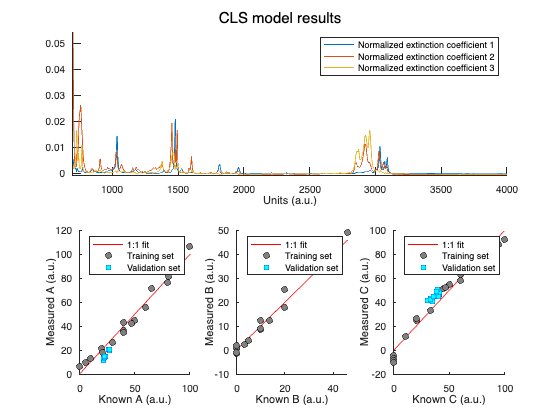

figure()
if validationDataPresent
    pnnl_model_plot_unformatted("CLS","Normalized extinction coefficient",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, K_cls, C_train, C_cls, C_validation, C_cls_pred)
elseif calibrationDataPresent
    pnnl_model_plot_unformatted("CLS","Normalized extinction coefficient",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, K_cls, C_train, C_cls)
end

### Basic PCR Plots

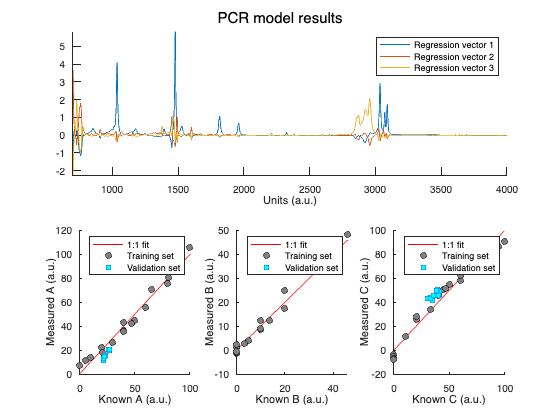

figure()
if validationDataPresent
    pnnl_model_plot_unformatted("PCR","Regression vector",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_pcr, C_train, C_pcr, C_validation, C_pcr_pred)
elseif calibrationDataPresent
    pnnl_model_plot_unformatted("PCR","Regression vector",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_pcr, C_train, C_pcr)
end

### Basic PLS Plots

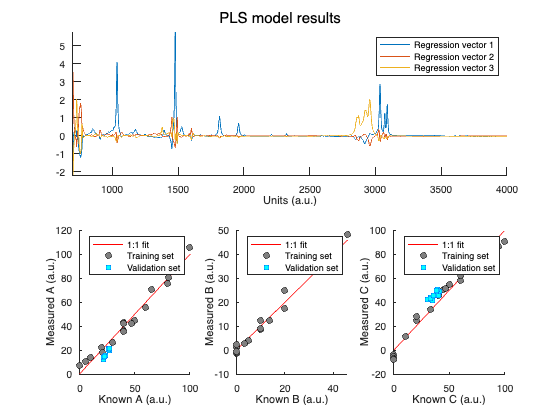

figure()
if validationDataPresent
    pnnl_model_plot_unformatted("PLS","Regression vector",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_pls, C_train, C_pls, C_validation, C_pls_pred)
elseif calibrationDataPresent
    pnnl_model_plot_unformatted("PLS","Regression vector",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_pls, C_train, C_pls)
end

### Basic PLS (mean centered) Plots

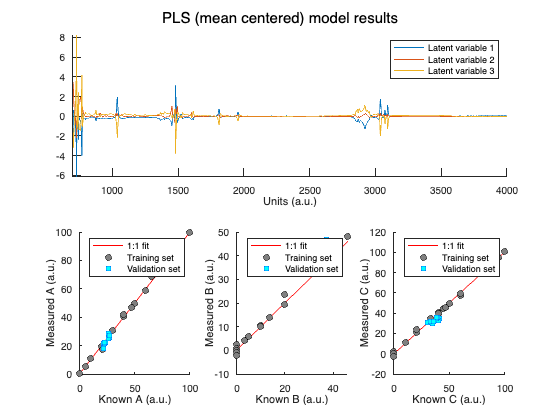

figure()
if validationDataPresent
    pnnl_model_plot_unformatted("PLS (mean centered)","Latent variable",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_plsmc, C_train, C_plsmc, C_validation, C_plsmc_pred)
elseif calibrationDataPresent
    pnnl_model_plot_unformatted("PLS (mean centered)","Latent variable",Wavenumbers,ConstituentNames,WavenumberLabel,ConcentrationUnits, B_plsmc, C_train, C_plsmc)
end

## Next Steps

How do your models look? Do your extinction coefficients and regression vectors make sense, chemically speaking? PLS and PCR don't always represent pure chemical signatures, like CLS does, but they should at least have reasonable shapes based on the shape of your spectra. Do you see any outliers in the parity plots (known vs. measured concentrations)? 

If you're not happy with the results, here's a couple of things you can try:

- Alter the number of model components (*r*) in the PCR and PLS models

- Explore signal processing methods, such as derivatives, normalization, and baseline corrections

- Alter your training set (add more samples, remove redundant samples, etc. Literature on Design of Experiment techniques may help you!) 

If you're happy, but want to dive deeper, you can open the various function files called in this script, such as pnnl_cls.m, pnnl_pcr.m, and pnnl_pls.m. Try plotting different things, such as the V matrix in PCR or the W matric in PLS against Wavenumbers. 

%#ok<*ASGLU>

Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830